**Ionic Current Model of Bipolar Cells**

Set constants

% Timespan. sec.
tspan = [0, 5];

% Hyperpolarizing current injections. pA.
hyper_injections = [-30, -20, -10];
num_hyper = length(hyper_injections);

% Depolarizing current injections. pA.
depolar_injections = [30, 20, 10];
num_de = length(depolar_injections);

*Compute voltage (hyperpolarizing)*

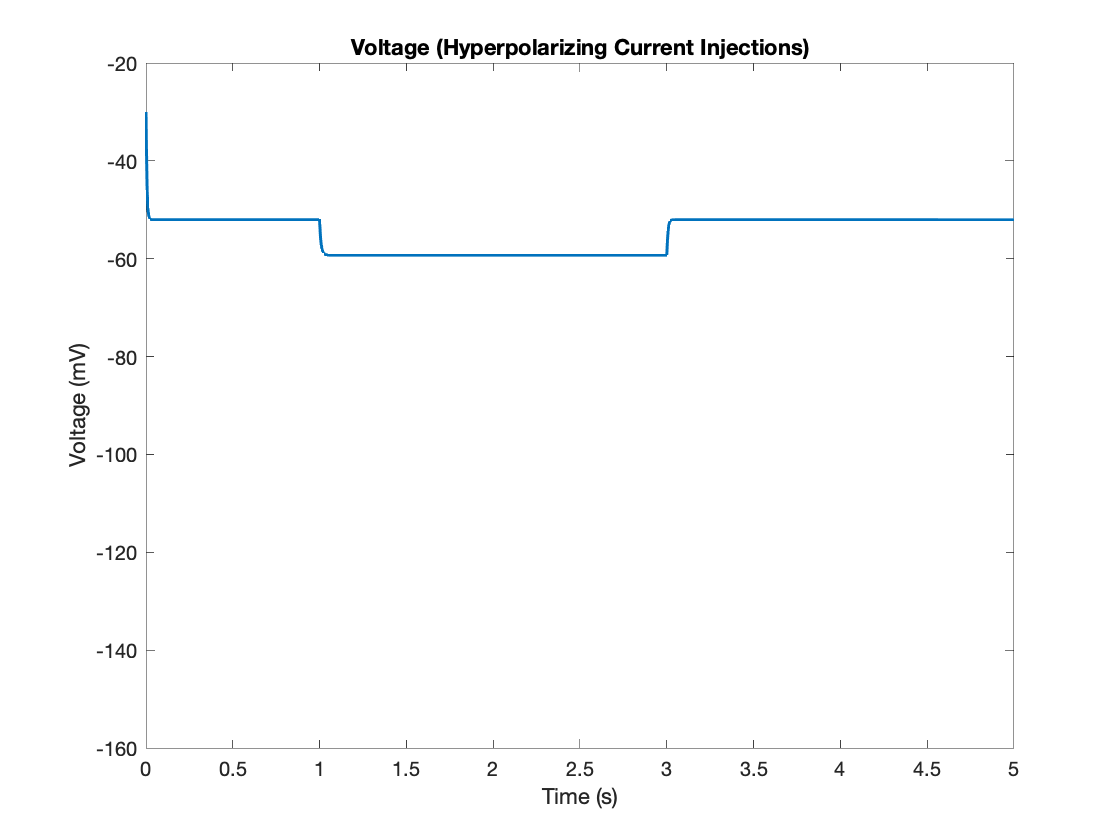

% Compute voltages.
[t_30, res_30] = calcV(tspan,hyper_injections(1));
V_30 = res_30(:,5);
[t_20, res_20] = calcV(tspan,hyper_injections(2));
V_20 = res_20(:,5);
[t_10, res_10] = calcV(tspan,hyper_injections(3));
V_10 = res_10(:,5);

% Interpolation to account for different sizes.
% maxLen = max([length(t_30), length(t_20), length(t_10)]);
% new_T = linspace(tspan(1), tspan(2), maxLen);
% newV_30 = interp1(t_30, V_30, new_T, 'spline');
% newV_20 = interp1(t_20, V_20, new_T, 'spline');
% newV_10 = interp1(t_10, V_10, new_T, 'spline');

% Plot the results.
plot(t_10, V_10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-160 -20])
title('Voltage (Hyperpolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')

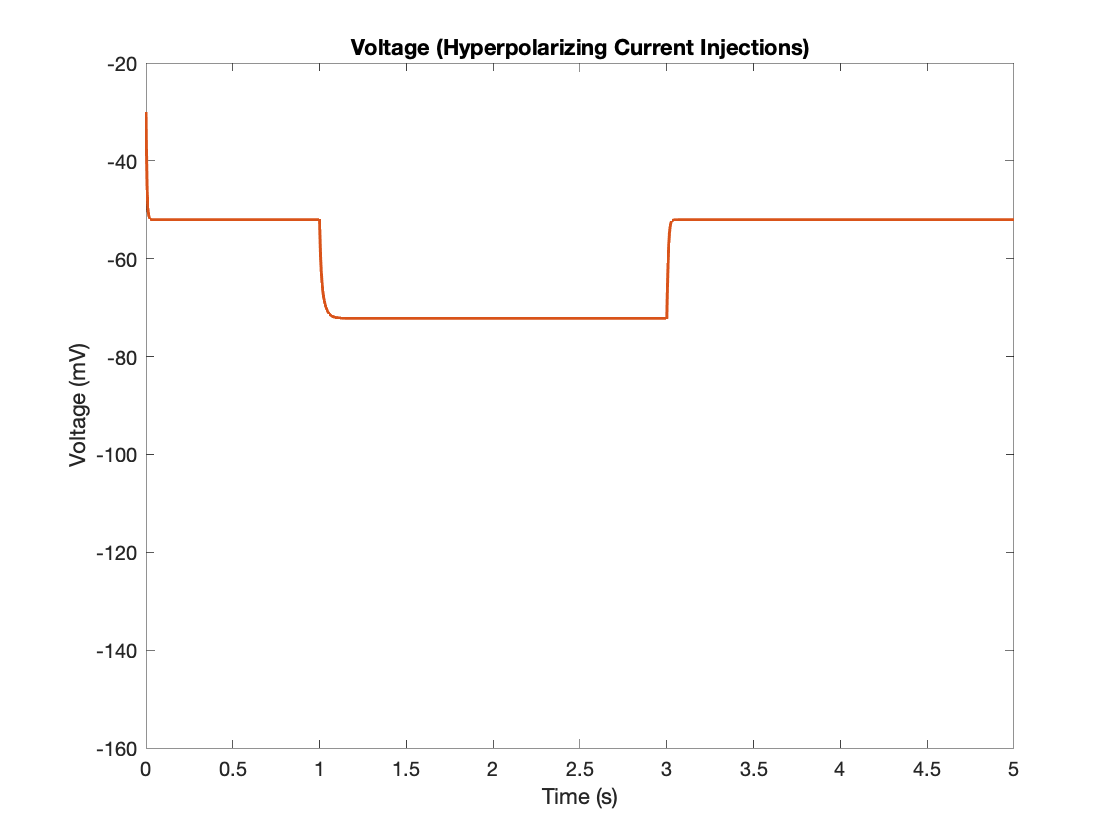

figure()

plot(t_20, V_20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-160 -20])
title('Voltage (Hyperpolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')

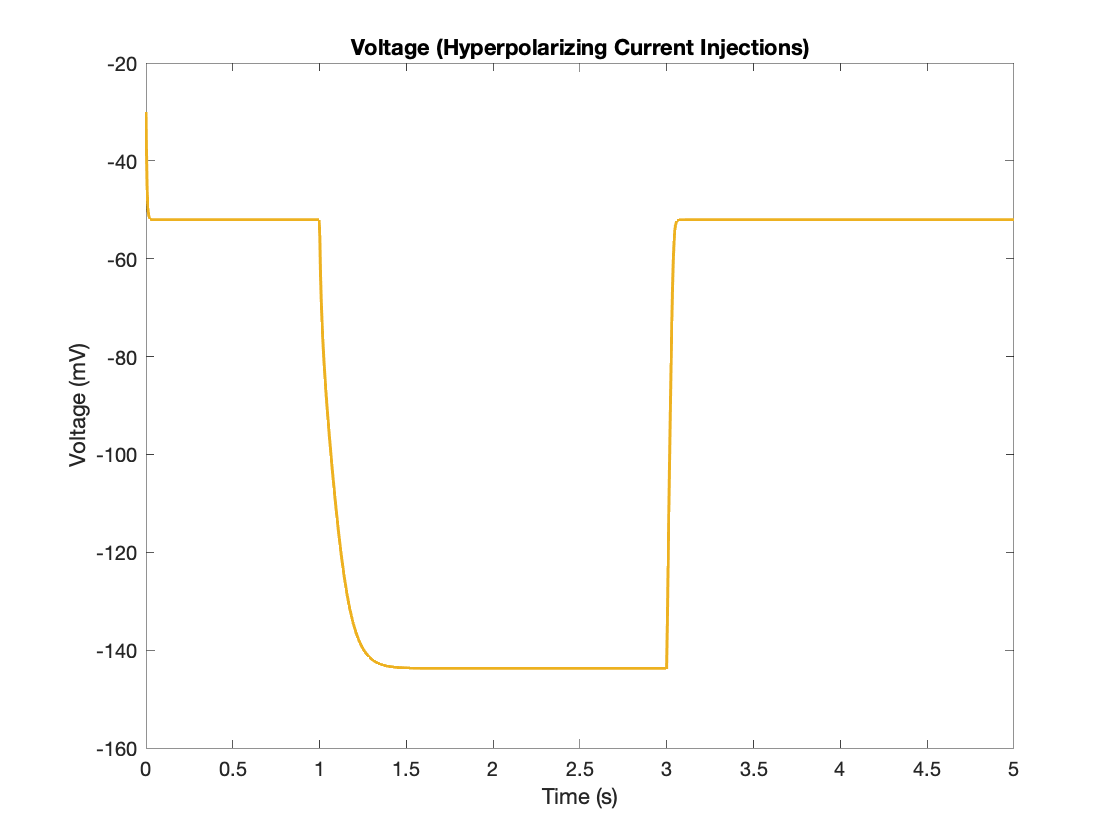

figure()

plot(t_30, V_30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-160 -20])
title('Voltage (Hyperpolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')

figure()
% legend('-10 pA injection','-20 pA injection','-30 pA injection')

*Compute voltage (depolarizing)*

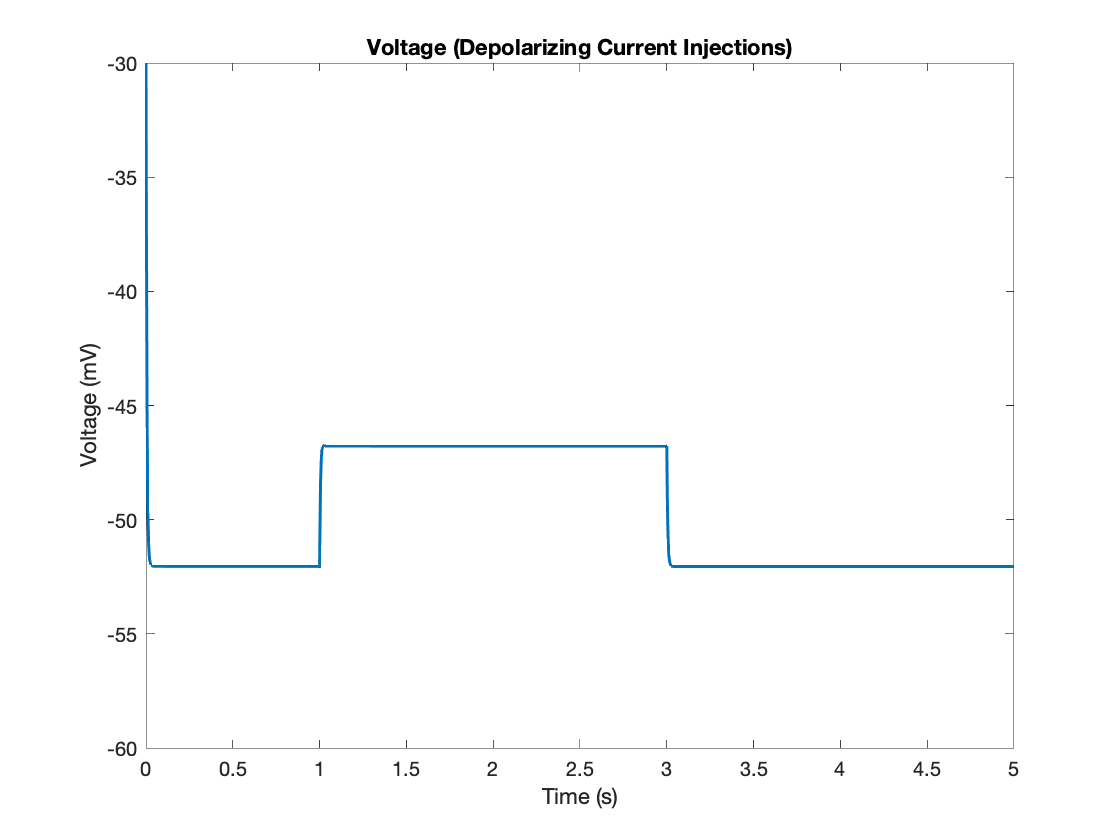

% Compute voltages.
[t30, res30] = calcV(tspan,depolar_injections(1));
V30 = res30(:,5);
[t20, res20] = calcV(tspan,depolar_injections(2));
V20 = res20(:,5);
[t10, res10] = calcV(tspan,depolar_injections(3));
V10 = res10(:,5);

% Interpolation to account for different sizes.
% maxLen = max([length(t30), length(t20), length(t10)]);
% newT = linspace(tspan(1), tspan(2), maxLen);
% newV30 = interp1(t30, V30, newT, 'spline');
% newV20 = interp1(t20, V20, newT, 'spline');
% newV10 = interp1(t10, V10, newT, 'spline');

% Plot the results.
plot(t10, V10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-60 -30])
title('Voltage (Depolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')

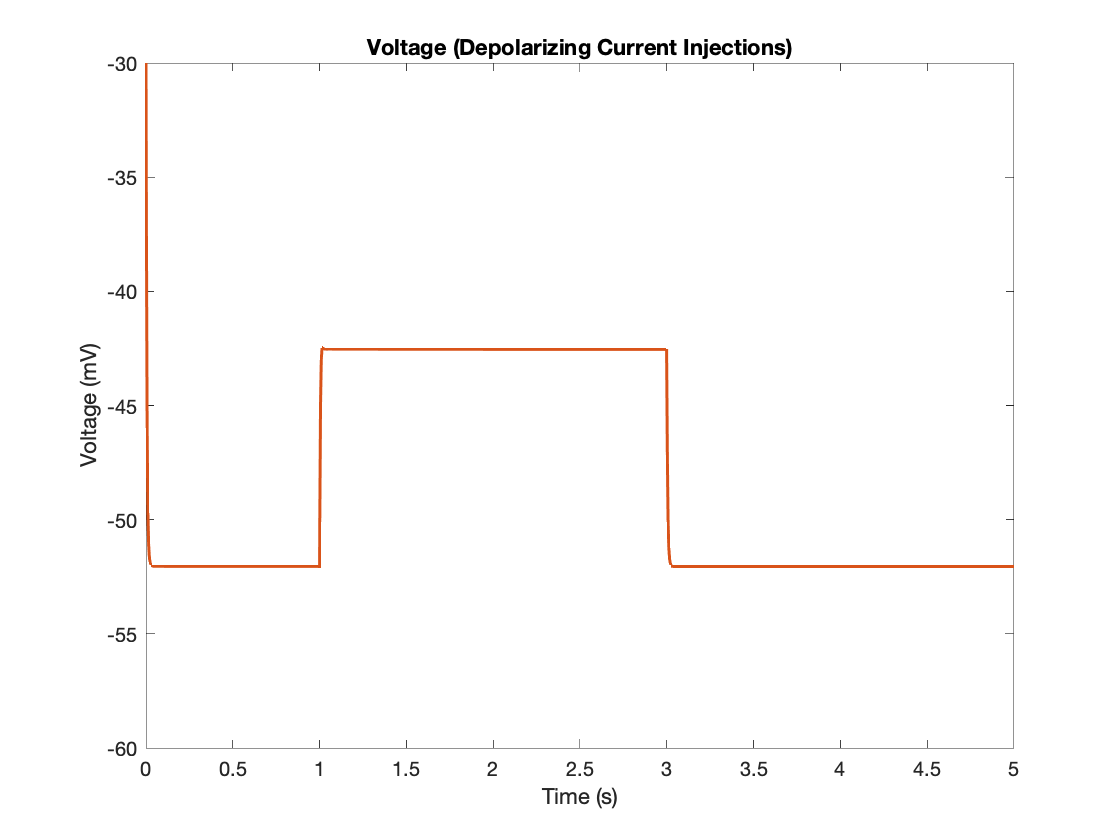

figure()

plot(t20, V20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-60 -30])
title('Voltage (Depolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')

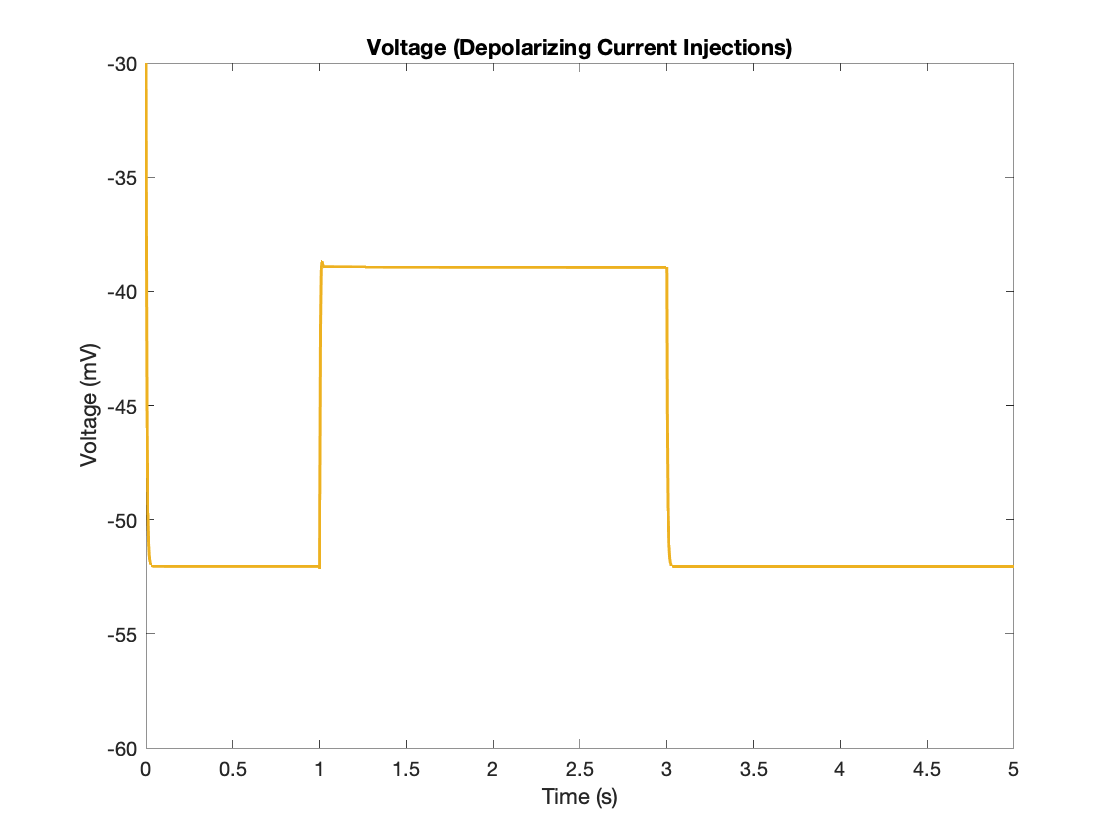

figure()

plot(t30, V30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-60 -30])
title('Voltage (Depolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')

figure()
% legend('10 pA injection','20 pA injection', '30 pA injection')

*Calcium current (hyperpolarizing)*

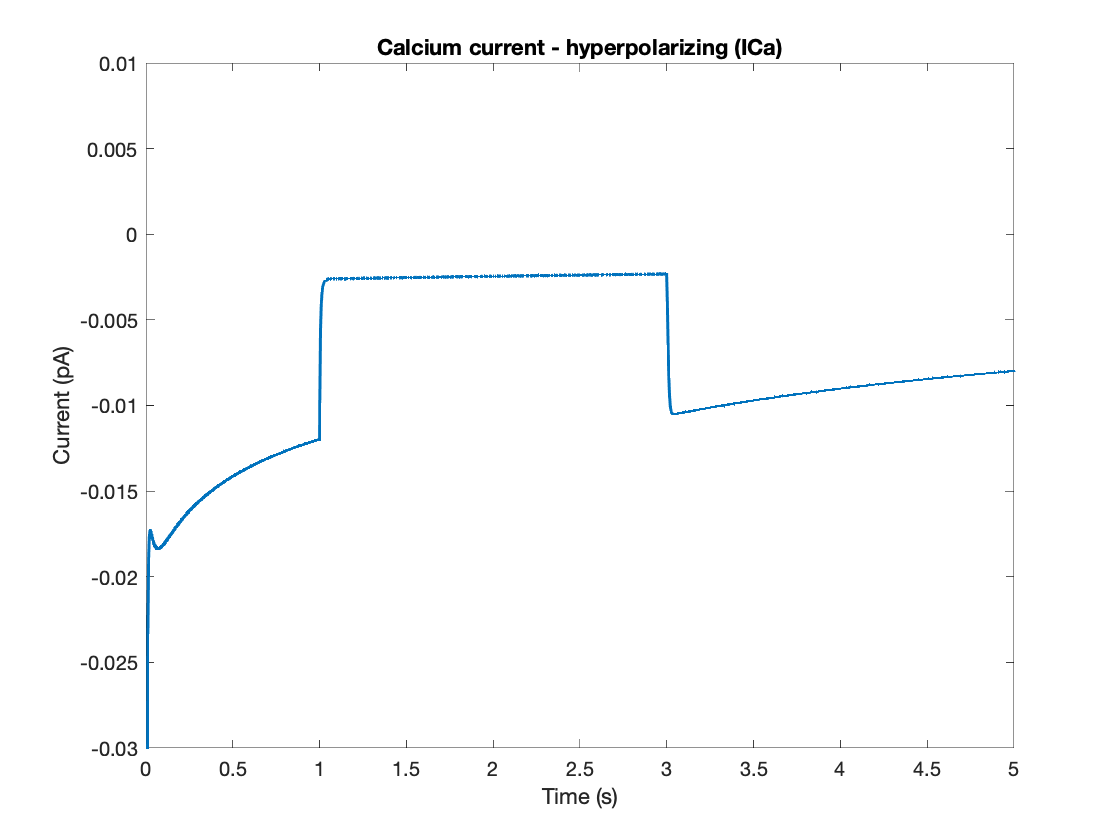

% Compute currents.
mCa_30 = res_30(:,3);
Cas_30 = res_30(:,11);
ICa_30 = calcICa(t_30, mCa_30, Cas_30, V_30);
mCa_20 = res_20(:,3);
Cas_20 = res_20(:,11);
ICa_20 = calcICa(t_20, mCa_20, Cas_20, V_20);
mCa_10 = res_10(:,3);
Cas_10 = res_10(:,11);
ICa_10 = calcICa(t_10, mCa_10, Cas_10, newV_10);

% Plot the results.
plot(t_10, ICa_10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-0.03 0.01])
title('Calcium current - hyperpolarizing (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')

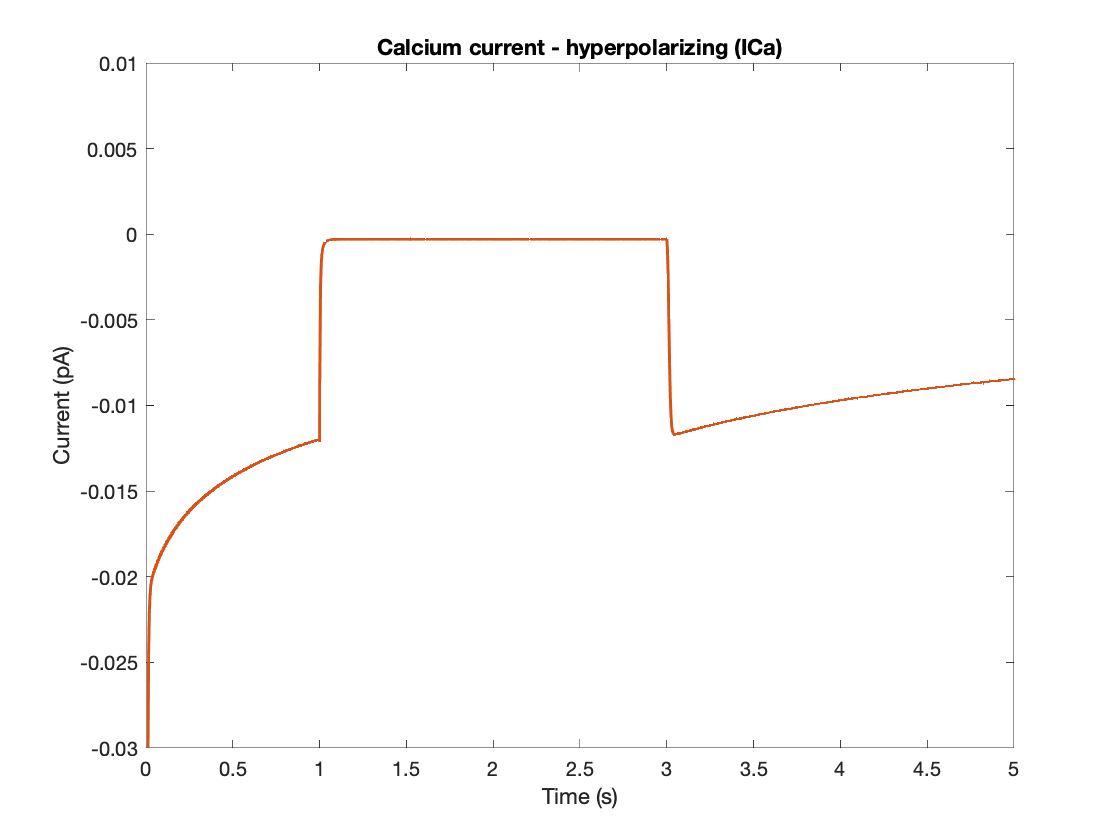

figure()

plot(t_20, ICa_20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-0.03 0.01])
title('Calcium current - hyperpolarizing (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')

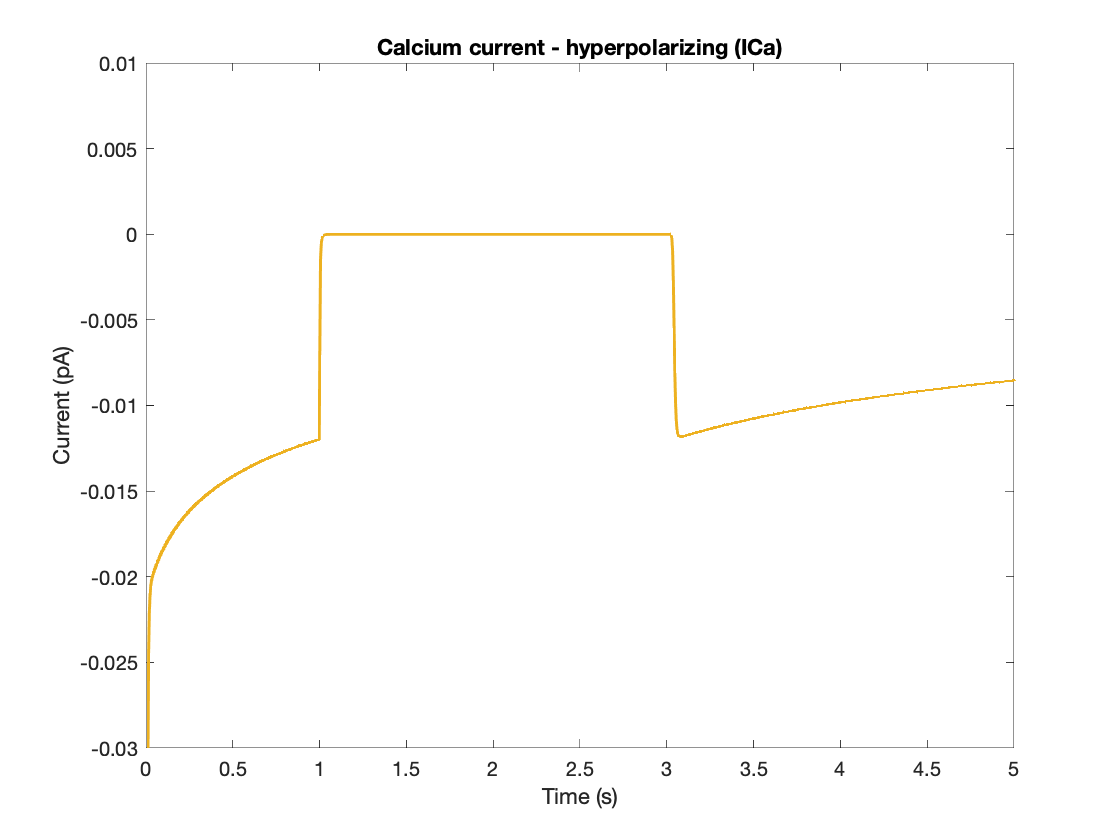

figure()

plot(t_30, ICa_30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-0.03 0.01])
title('Calcium current - hyperpolarizing (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()
% legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Calcium current (depolarizing)*

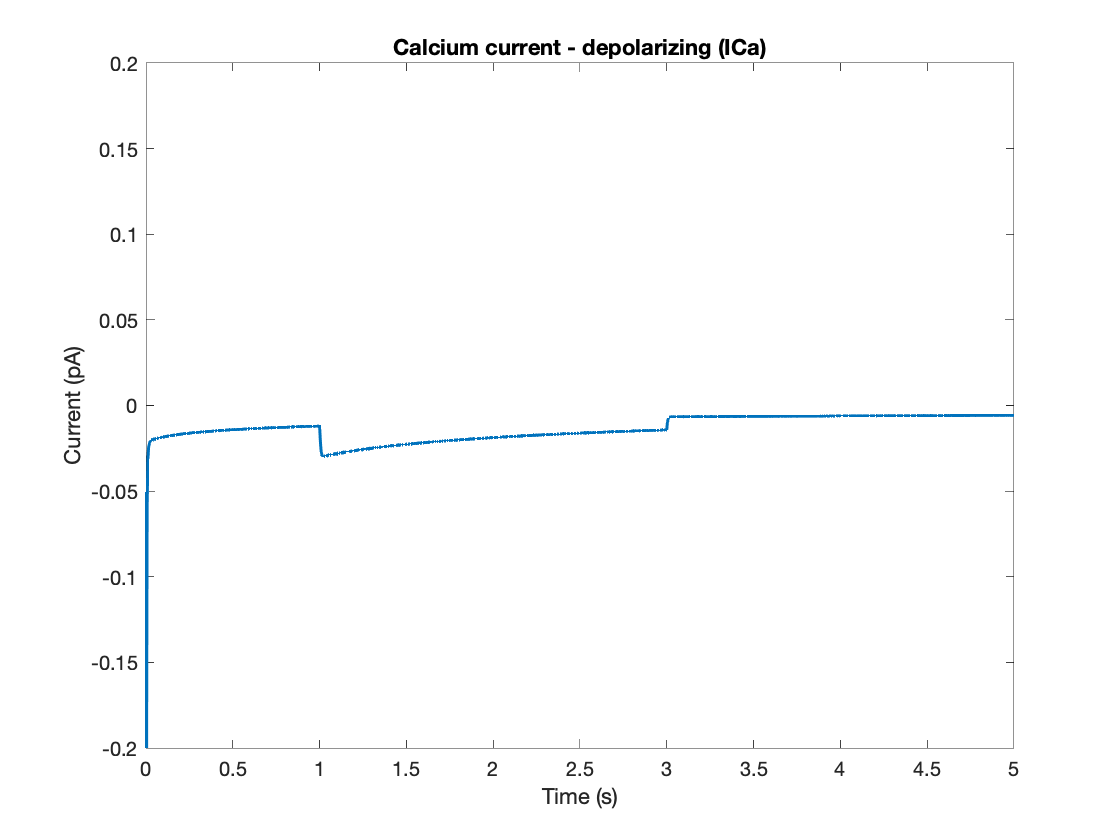

% Compute currents.
mCa30 = res30(:,3);
Cas30 = res30(:,11);
ICa30 = calcICa(t30, mCa30, Cas30, V30);
mCa20 = res20(:,3);
Cas20 = res20(:,11);
ICa20 = calcICa(t20, mCa20, Cas20, V20);
mCa10 = res10(:,3);
Cas10 = res10(:,11);
ICa10 = calcICa(t10, mCa10, Cas10, V10);

% Plot the results.
plot(t10, ICa10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-0.2 0.2])
title('Calcium current - depolarizing (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')

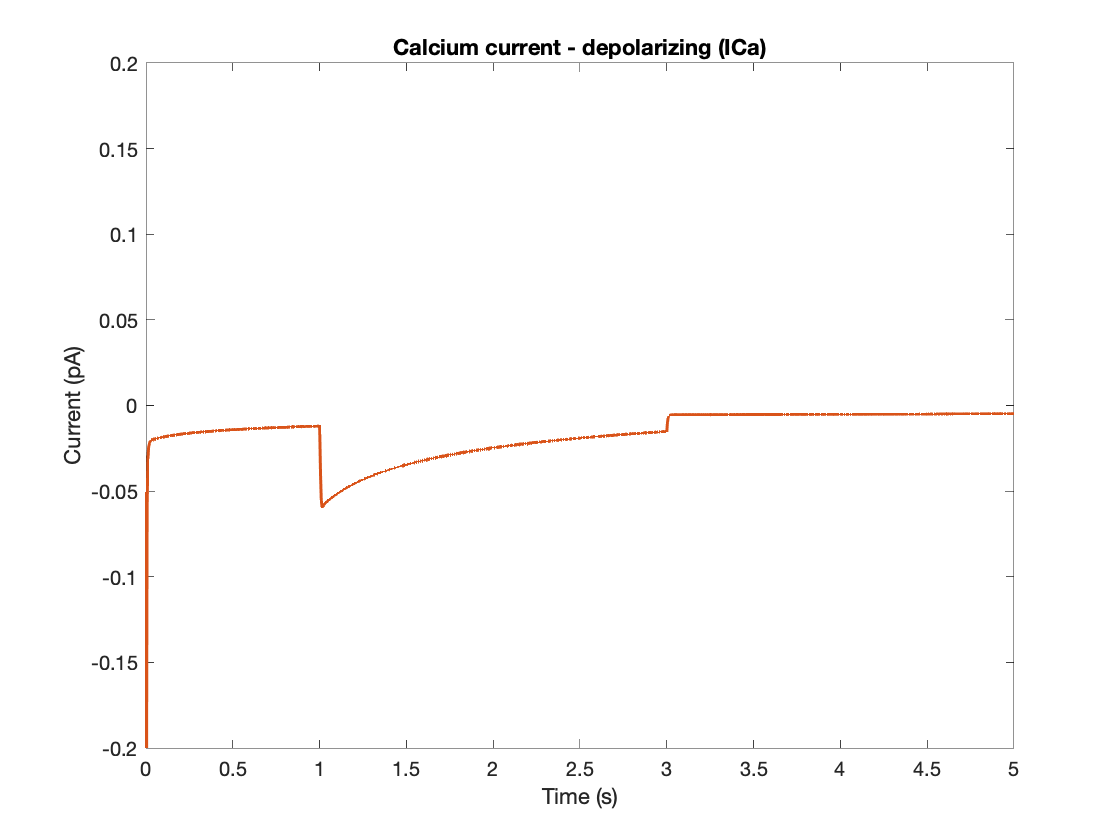

figure()

plot(t20, ICa20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-0.2 0.2])
title('Calcium current - depolarizing (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')

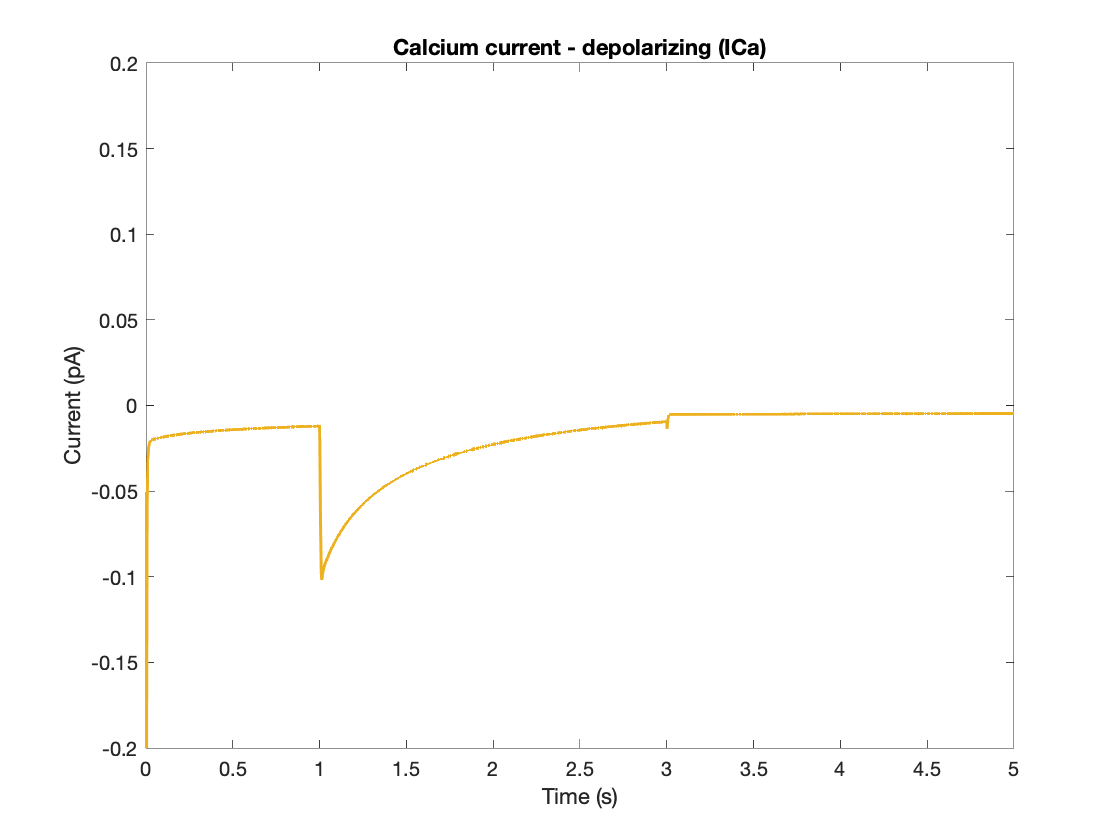

figure()

plot(t30, ICa30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-0.2 0.2])
title('Calcium current - depolarizing (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()
% legend('30 pA injection','20 pA injection','10 pA injection')

*Calcium-dependent K current (hyperpolarizing)*

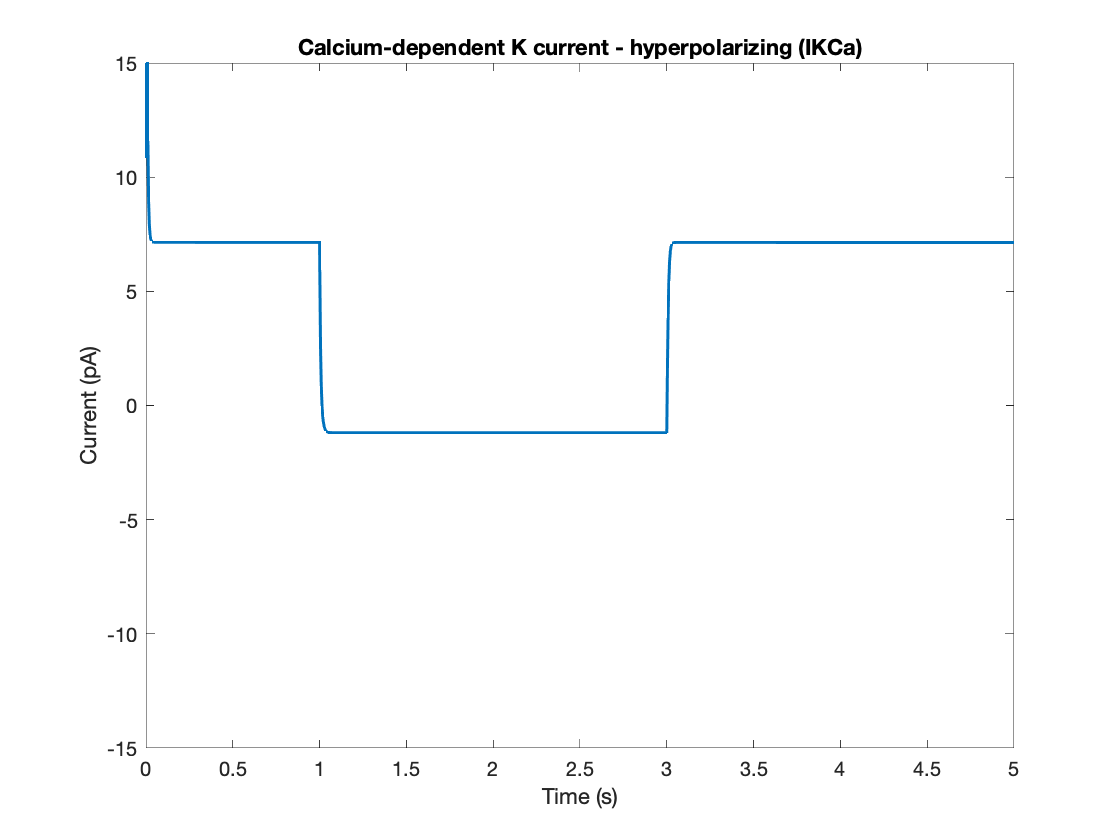

% Compute currents.
mKc_30 = res_30(:,4);
Cas_30 = res_30(:,11);
IKCa_30 = calcIKCa(t_30, mKc_30, Cas_30, V_30);
mKc_20 = res_20(:,4);
Cas_20 = res_20(:,11);
IKCa_20 = calcIKCa(t_20, mKc_20, Cas_20, V_20);
mKc_10 = res_10(:,4);
Cas_10 = res_10(:,11);
IKCa_10 = calcIKCa(t_10, mKc_10, Cas_10, V_10);

% Plot the results.
plot(t_10, IKCa_10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-15 15])
title('Calcium-dependent K current - hyperpolarizing (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')

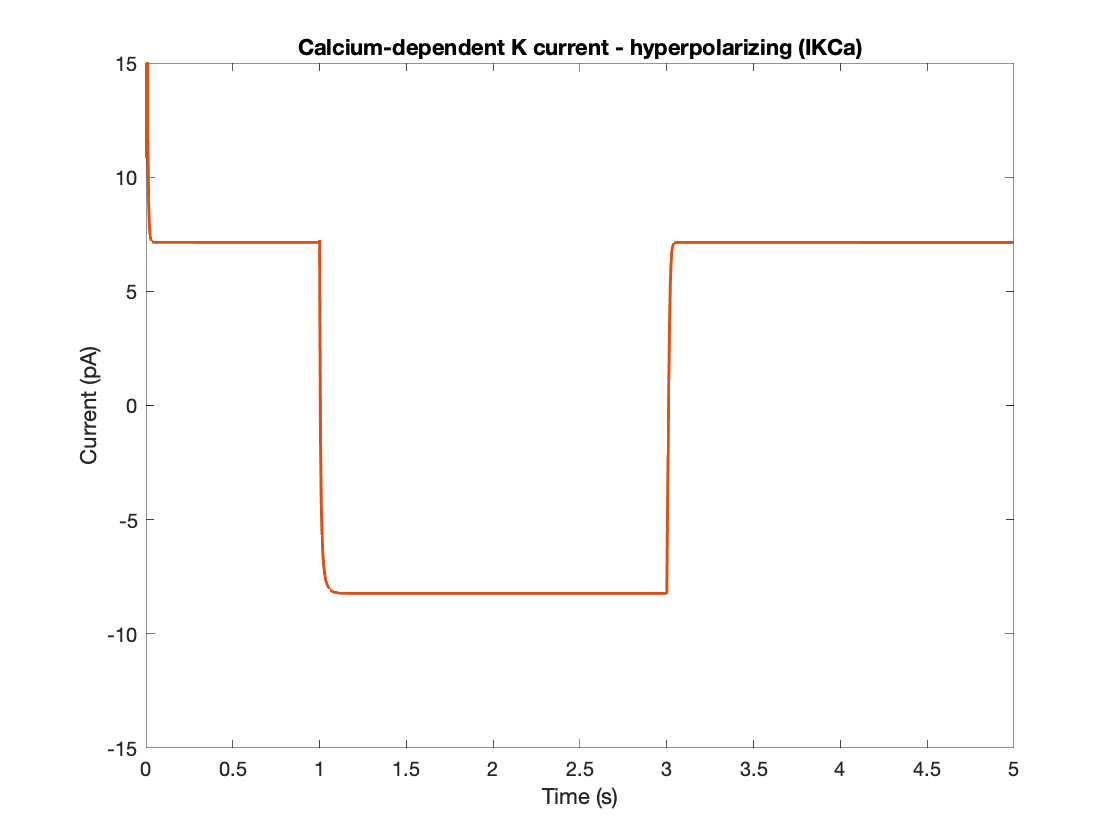

figure()

plot(t_20, IKCa_20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-15 15])
title('Calcium-dependent K current - hyperpolarizing (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')

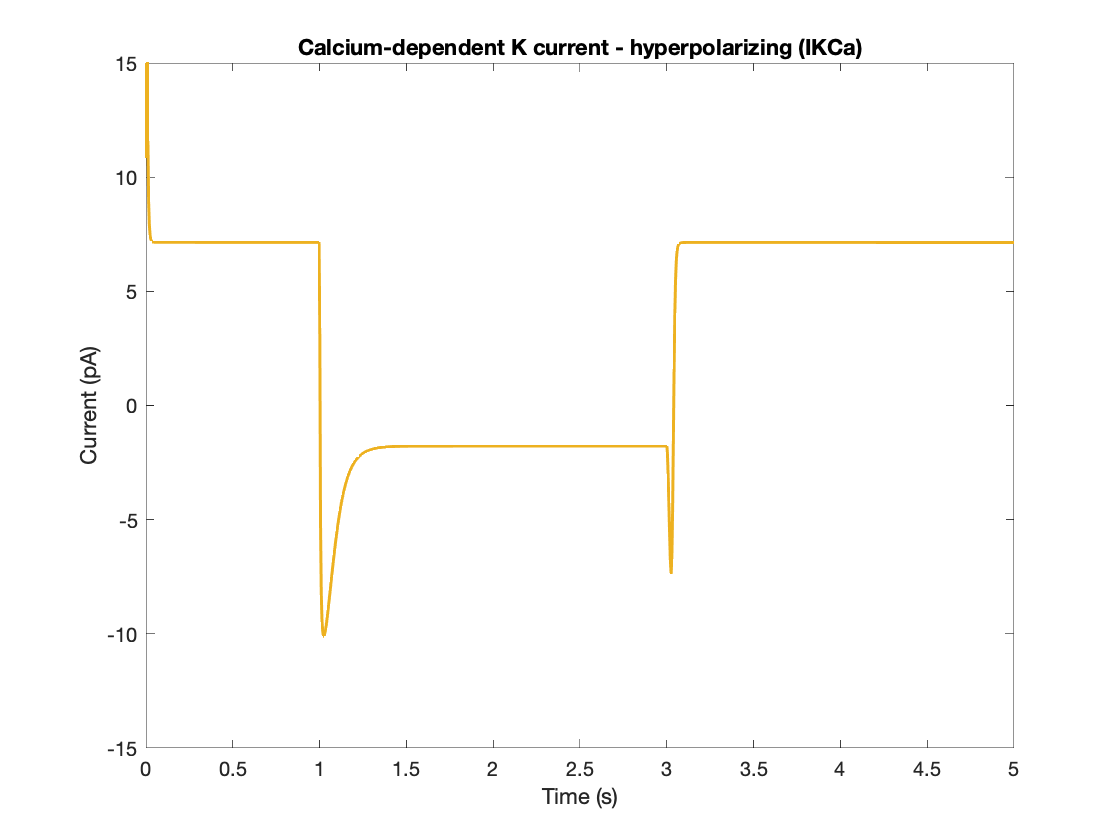

figure()

plot(t_30, IKCa_30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-15 15])
title('Calcium-dependent K current - hyperpolarizing (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()
% legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Calcium-dependent K current (depolarizing)*

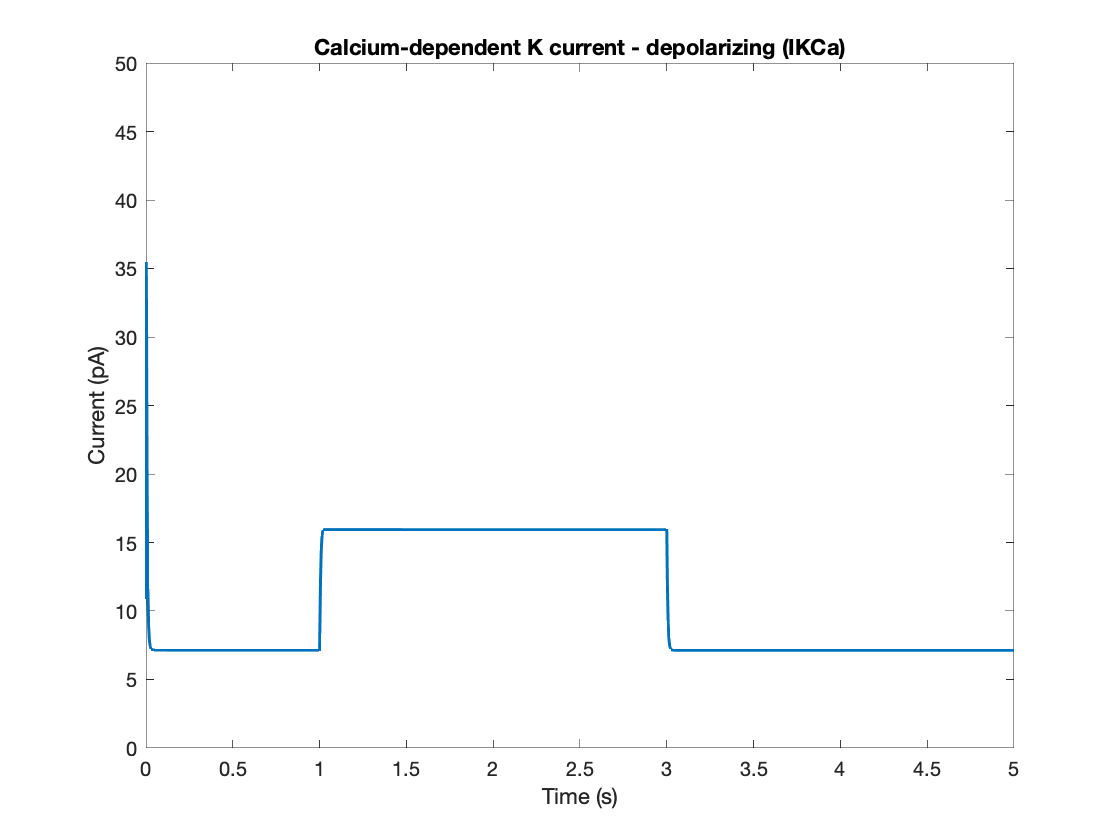

% Compute currents.
mKc30 = res30(:,4);
Cas30 = res30(:,11);
IKCa30 = calcIKCa(t30, mKc30, Cas30, V30);
mKc20 = res20(:,4);
Cas20 = res20(:,11);
IKCa20 = calcIKCa(t20, mKc20, Cas20, V20);
mKc10 = res10(:,4);
Cas10 = res10(:,11);
IKCa10 = calcIKCa(t10, mKc10, Cas10, V10);

% Plot the results.
plot(t10, IKCa10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([0 50])
title('Calcium-dependent K current - depolarizing (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')

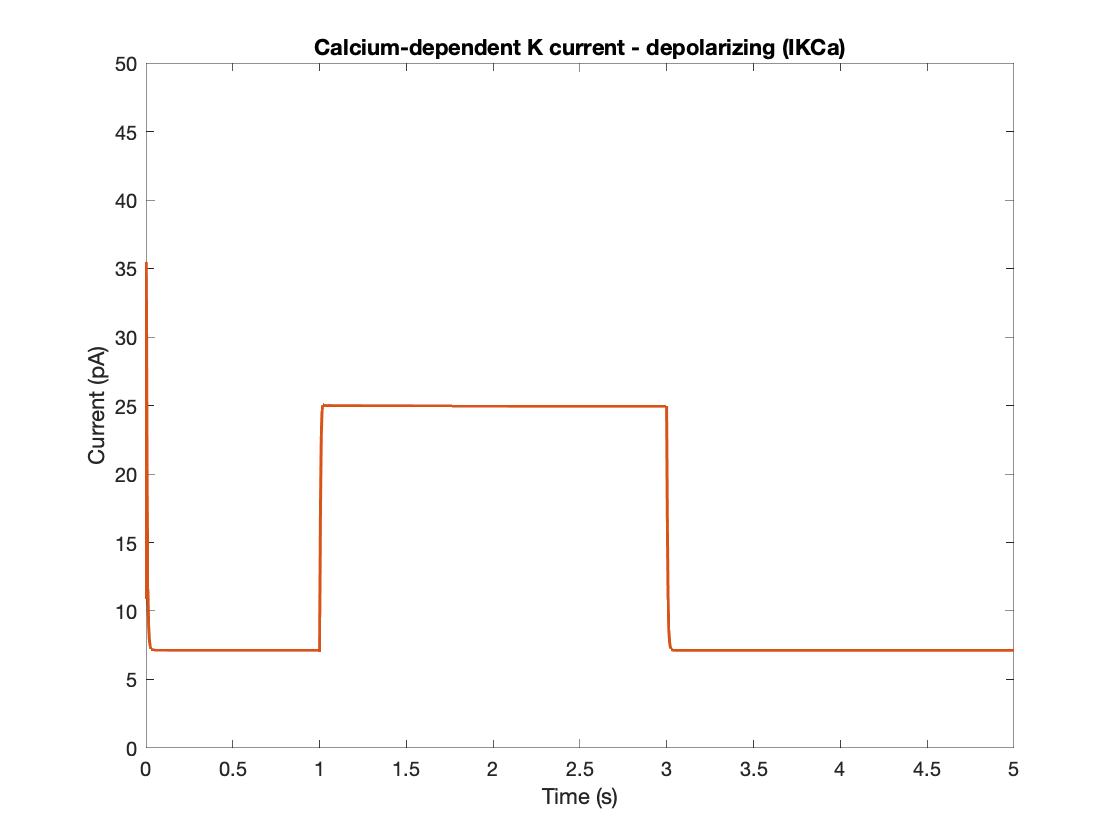

figure()

plot(t20, IKCa20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([0 50])
title('Calcium-dependent K current - depolarizing (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')

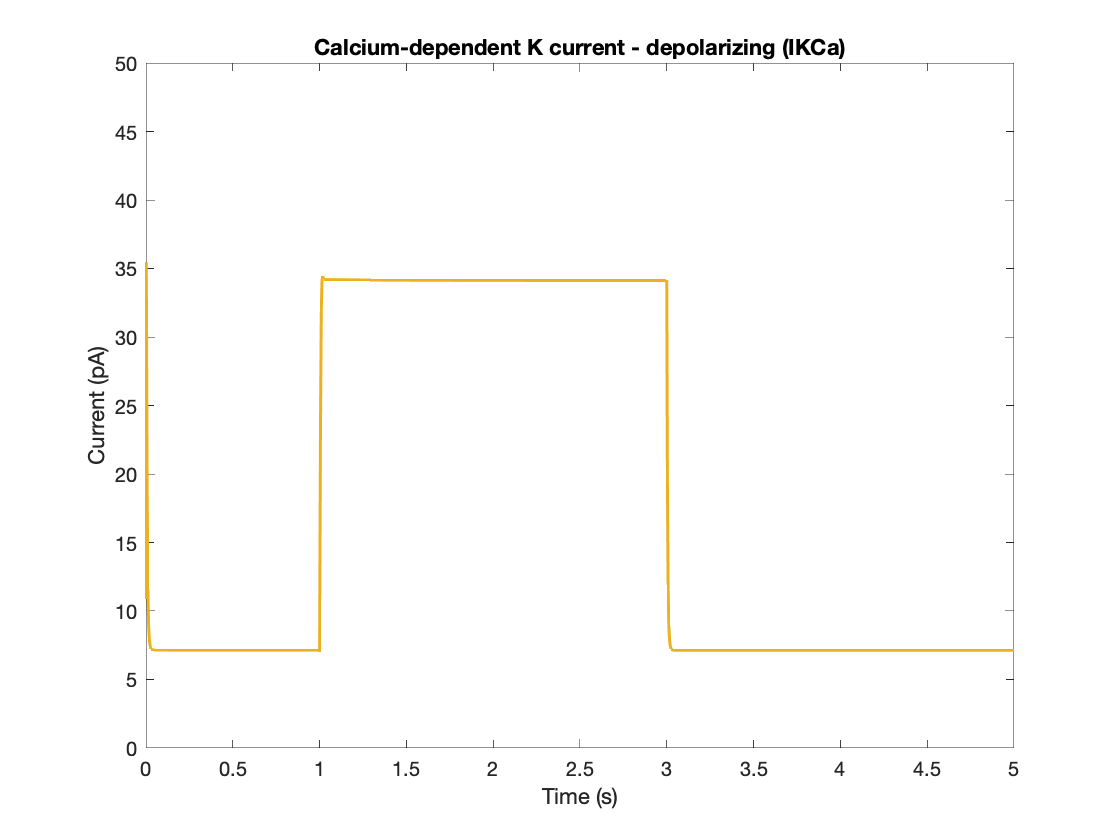

figure()

plot(t30, IKCa30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([0 50])
title('Calcium-dependent K current - depolarizing (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()
% legend('30 pA injection','20 pA injection','10 pA injection')

*Delayed rectifying potassium current (hyperpolarizing)*

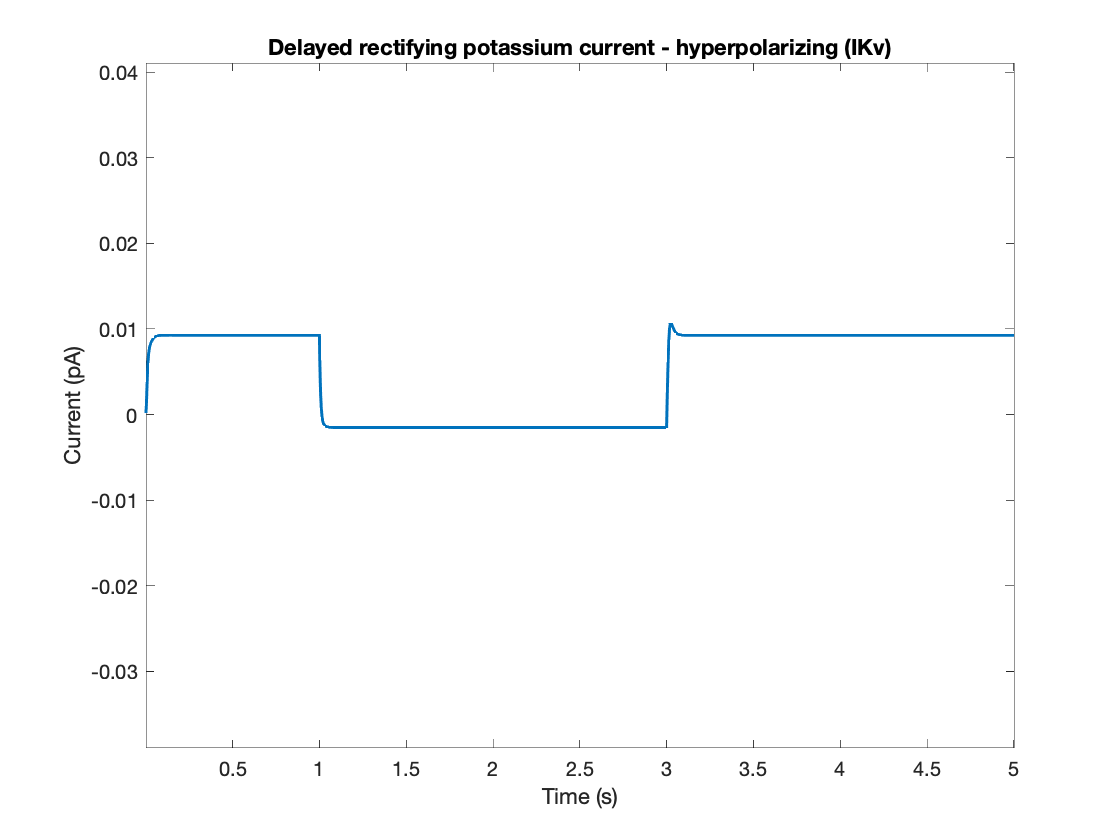

% Compute currents.
mKv_30 = res_30(:,1);
hKv_30 = res_30(:,2);
IKv_30 = calcIKv(t_30, mKv_30, hKv_30, V_30);
mKv_20 = res_20(:,1);
hKv_20 = res_20(:,2);
IKv_20 = calcIKv(t_20, mKv_20, hKv_20, V_20);
mKv_10 = res_10(:,1);
hKv_10 = res_10(:,2);
IKv_10 = calcIKv(t_10, mKv_10, hKv_10, V_10);

% Plot the results.
plot(t_10, IKv_10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-0.04 0.04])
title('Delayed rectifying potassium current - hyperpolarizing (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')

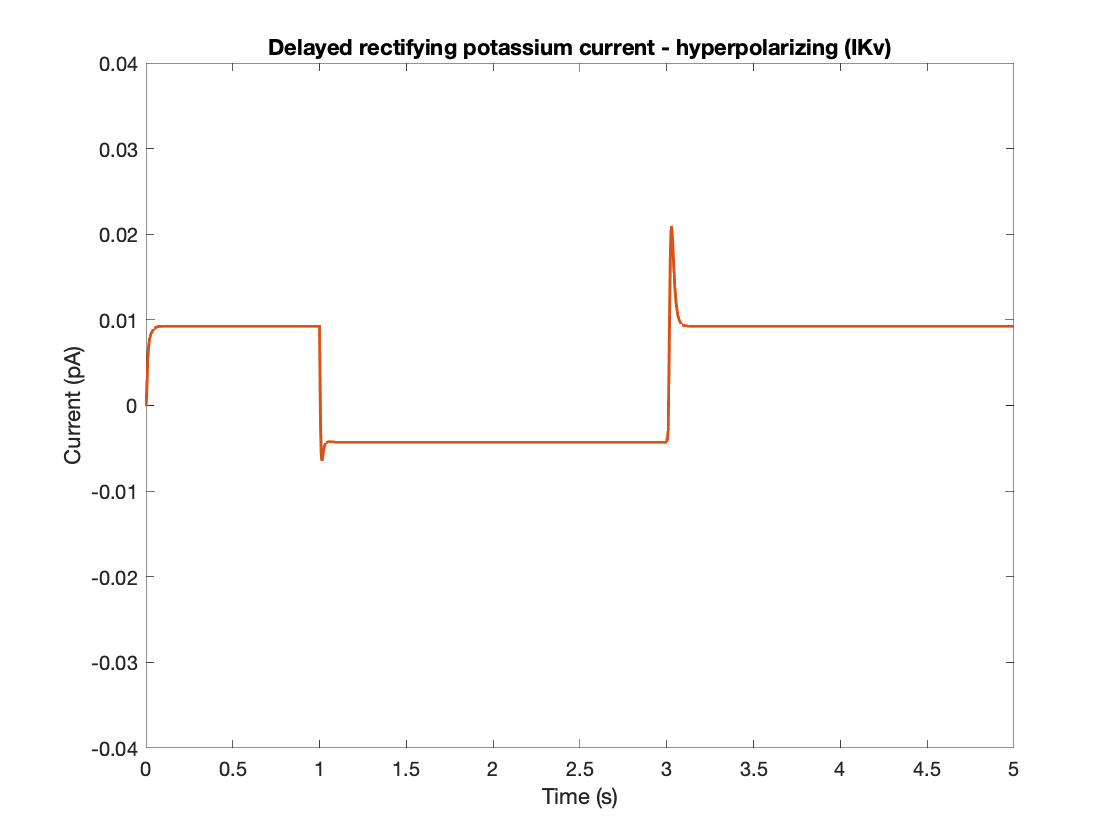

figure()

plot(t_20, IKv_20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-0.04 0.04])
title('Delayed rectifying potassium current - hyperpolarizing (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')

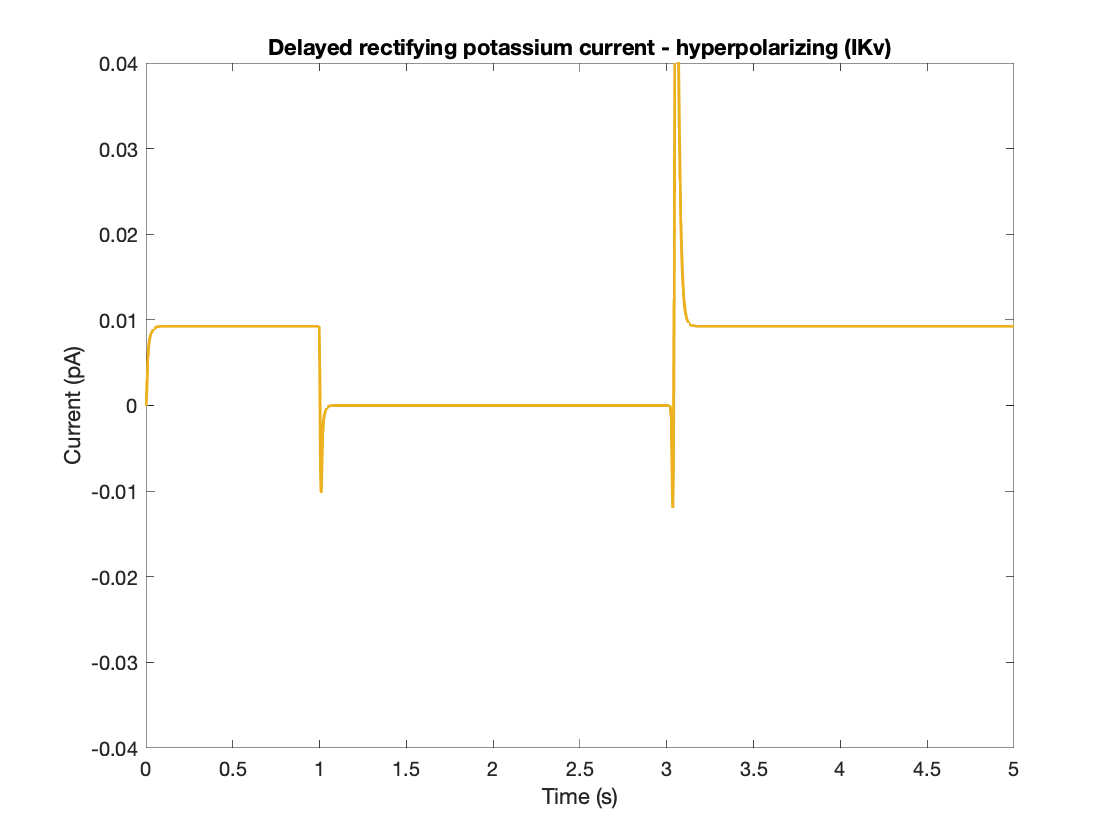

figure()

plot(t_30, IKv_30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-0.04 0.04])
title('Delayed rectifying potassium current - hyperpolarizing (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()
% legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Delayed rectifying potassium current (depolarizing)*

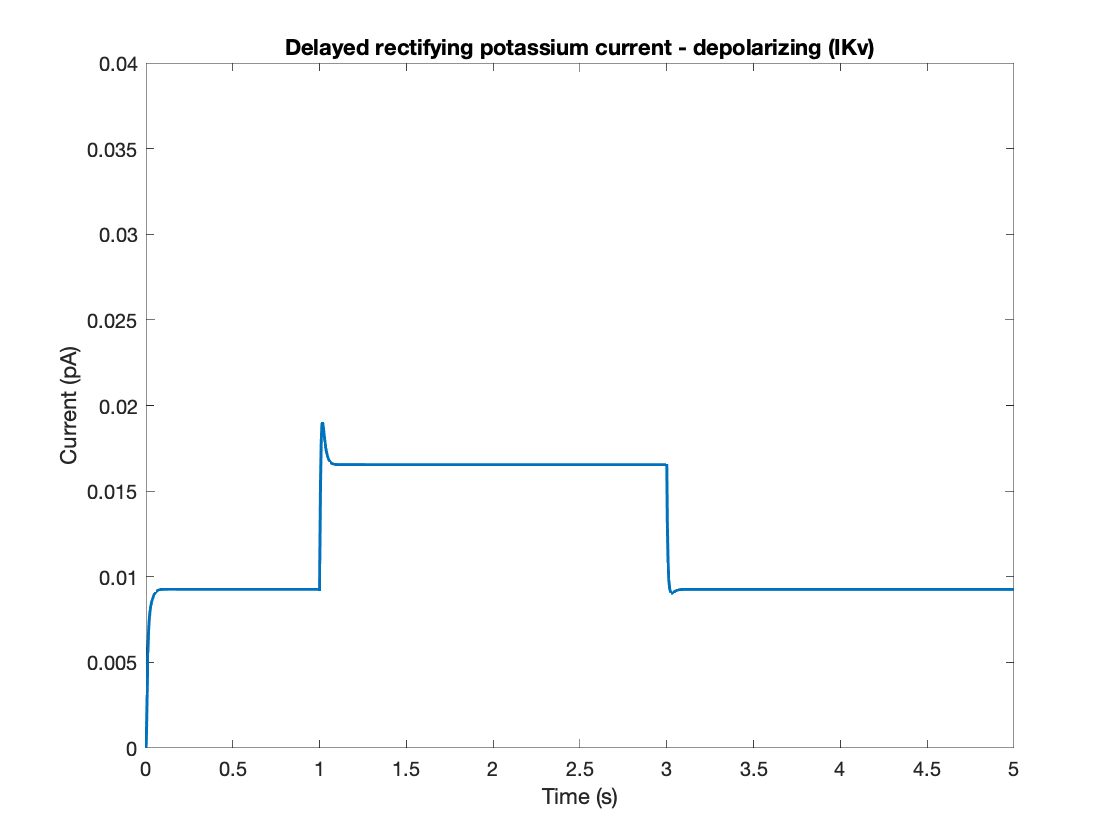

% Compute currents.
mKv30 = res30(:,1);
hKv30 = res30(:,2);
IKv30 = calcIKv(t30, mKv30, hKv30, V30);
mKv20 = res20(:,1);
hKv20 = res20(:,2);
IKv20 = calcIKv(t20, mKv20, hKv20, V20);
mKv10 = res10(:,1);
hKv10 = res10(:,2);
IKv10 = calcIKv(t10, mKv10, hKv10, V10);

% Plot the results.
plot(t10, IKv10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([0 0.04])
title('Delayed rectifying potassium current - depolarizing (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')

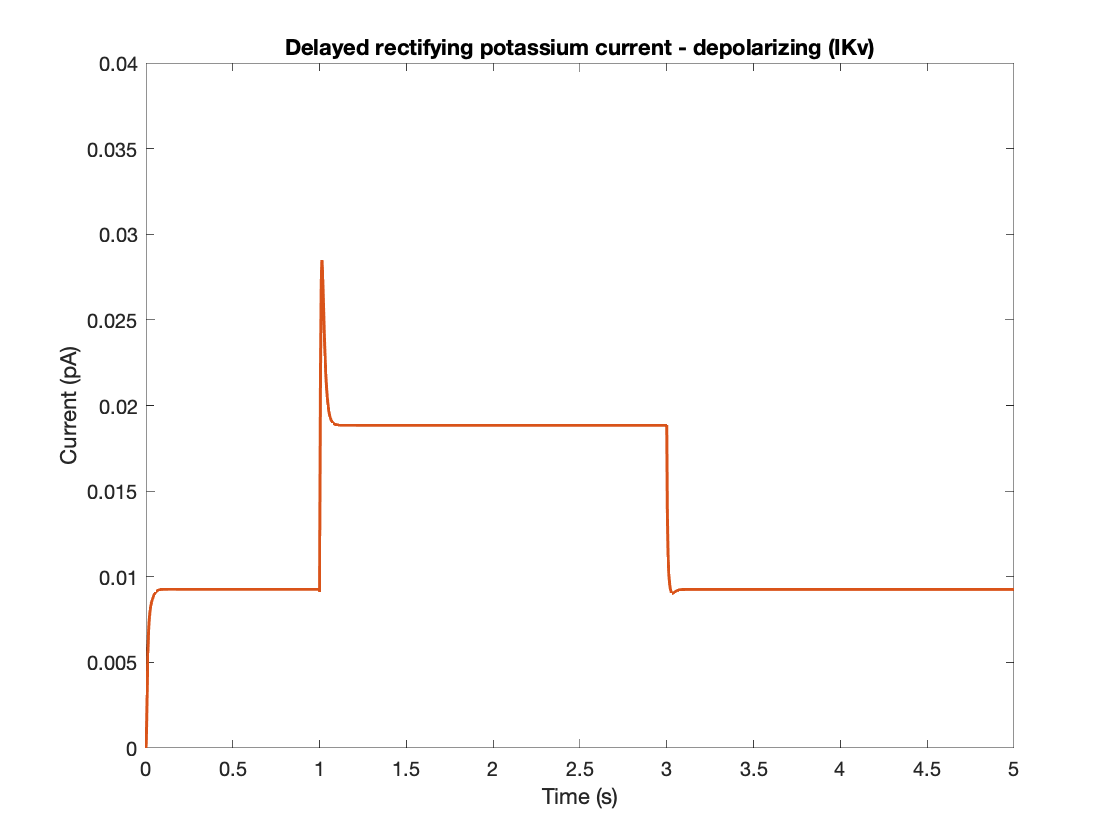


plot(t20, IKv20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([0 0.04])
title('Delayed rectifying potassium current - depolarizing (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')

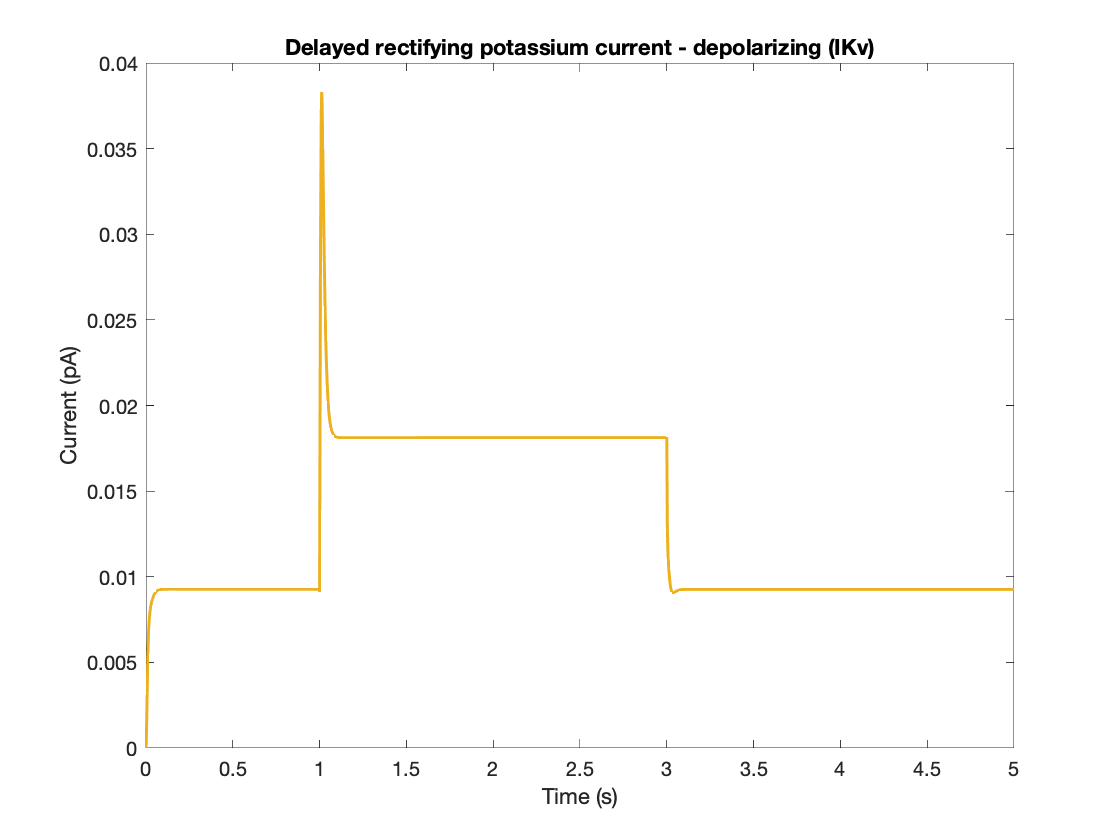


plot(t30, IKv30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([0 0.04])
title('Delayed rectifying potassium current - depolarizing (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')

% legend('30 pA injection','20 pA injection','10 pA injection')

*Hyperpolarization activated current (hyperpolarizing)*

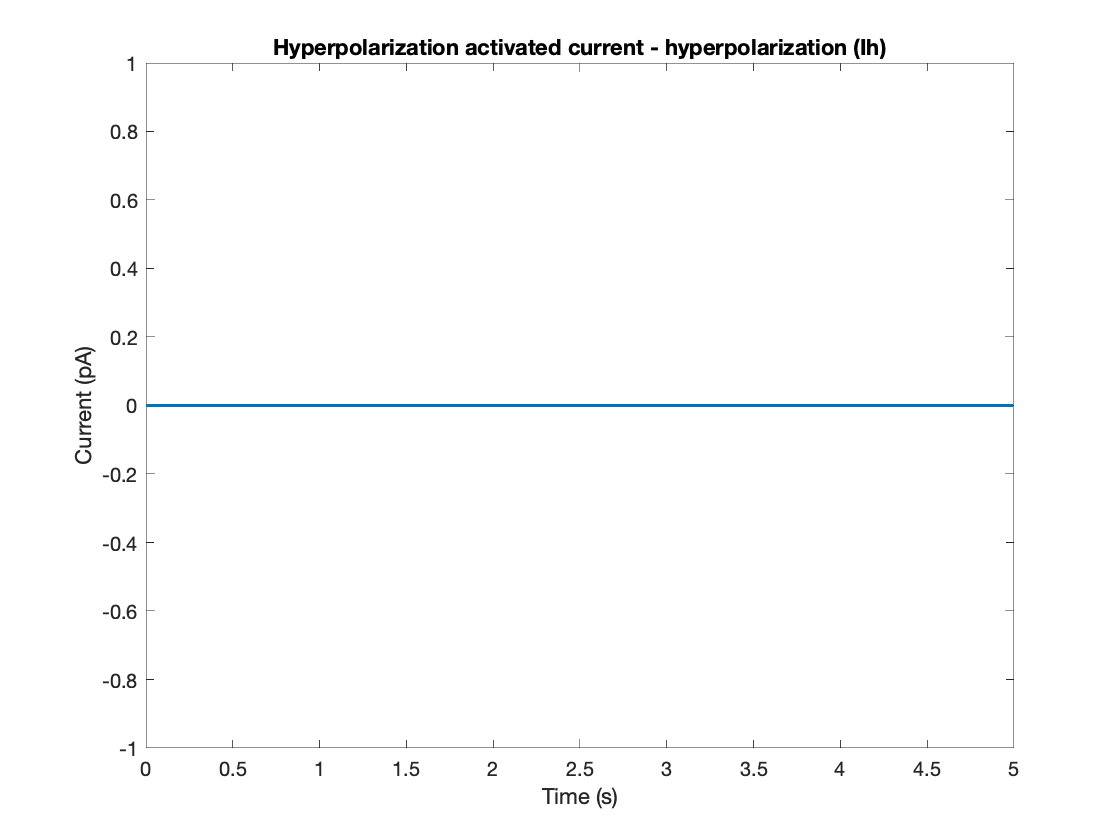

% Compute currents.
O1_30 = res_30(:,8);
O2_30 = res_30(:,9);
O3_30 = res_30(:,10);
Ih_30 = calcIh(t_30, O1_30, O2_30, O3_30, V_30);
O1_20 = res_20(:,8);
O2_20 = res_20(:,9);
O3_20 = res_20(:,10);
Ih_20 = calcIh(t_20, O1_20, O2_20, O3_20, V_20);
O1_10 = res_10(:,8);
O2_10 = res_10(:,9);
O3_10 = res_10(:,10);
Ih_10 = calcIh(t_10, O1_10, O2_10, O3_10, V_10);

% Plot the results.
plot(t_10, Ih_10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-1 1])
title('Hyperpolarization activated current - hyperpolarization (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')

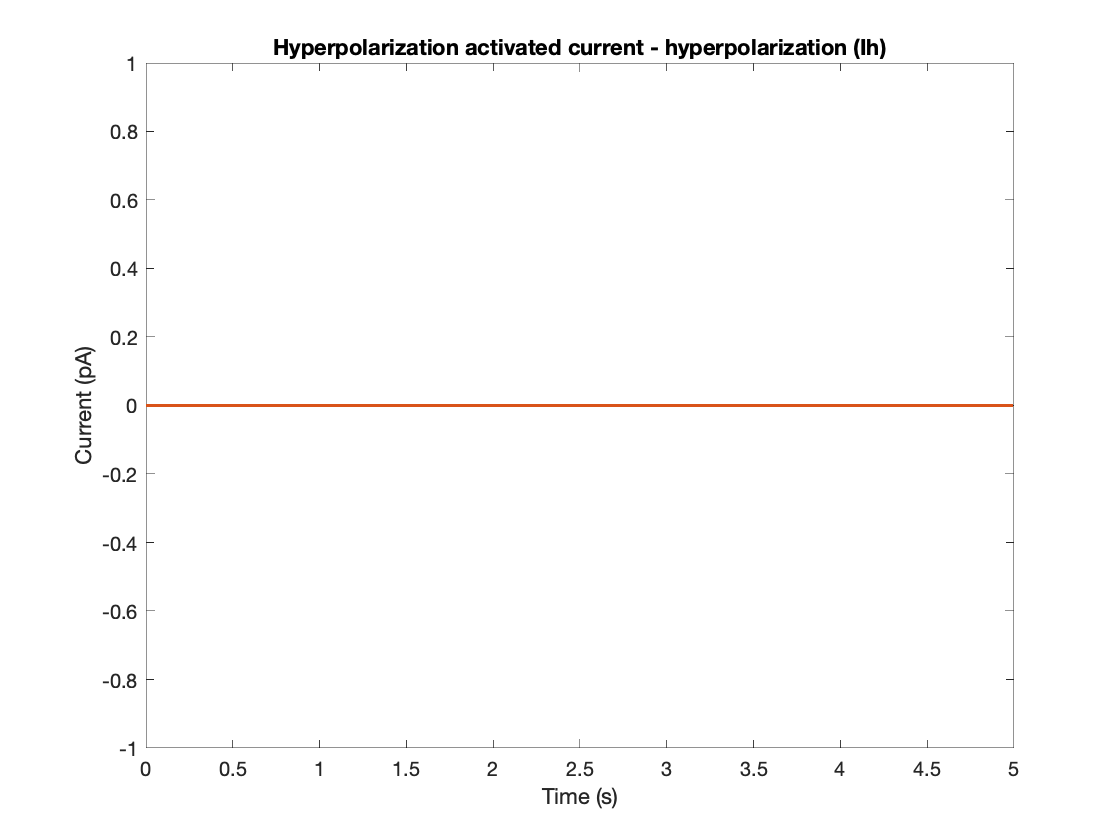

figure()

plot(t_20, Ih_20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-1 1])
title('Hyperpolarization activated current - hyperpolarization (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')

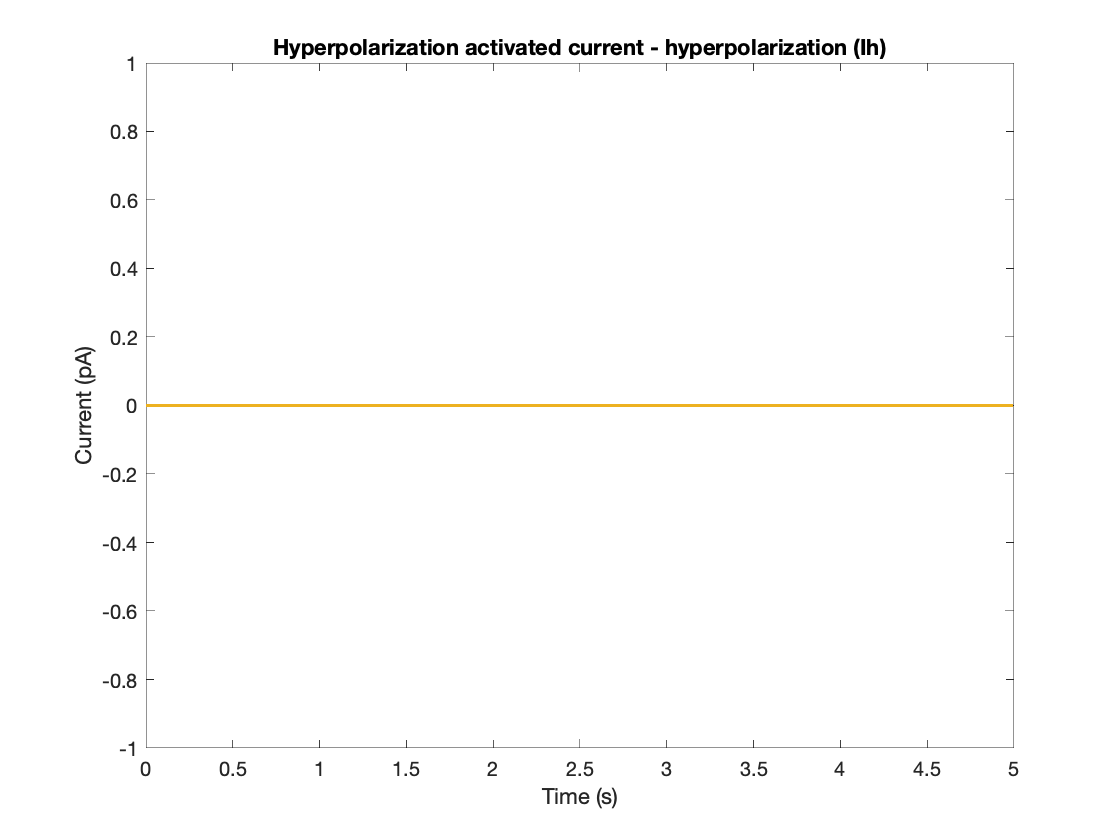

figure()

plot(t_30, Ih_30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-1 1])
title('Hyperpolarization activated current - hyperpolarization (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()
% legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Hyperpolarization activated current (depolarizing)*

% Compute currents.
O130 = res30(:,8);
O230 = res30(:,9);
O330 = res30(:,10);
Ih30 = calcIh(t30, O130, O230, O330, V30);
O120 = res20(:,8);
O220 = res20(:,9);
O320 = res20(:,10);
Ih20 = calcIh(t20, O120, O220, O320, V20);
O110 = res10(:,8);
O210 = res10(:,9);
O310 = res10(:,10);
Ih10 = calcIh(t10, O110, O210, O310, V10);

% Plot the results.
plot(t10, Ih10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-1 1])
title('Hyperpolarization activated current - depolarization (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()

plot(t20, Ih20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-1 1])
title('Hyperpolarization activated current - depolarization (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()

plot(t30, Ih30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-1 1])
title('Hyperpolarization activated current - depolarization (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()
% legend('30 pA injection','20 pA injection','10 pA injection')

*Leakage current (hyperpolarization)*

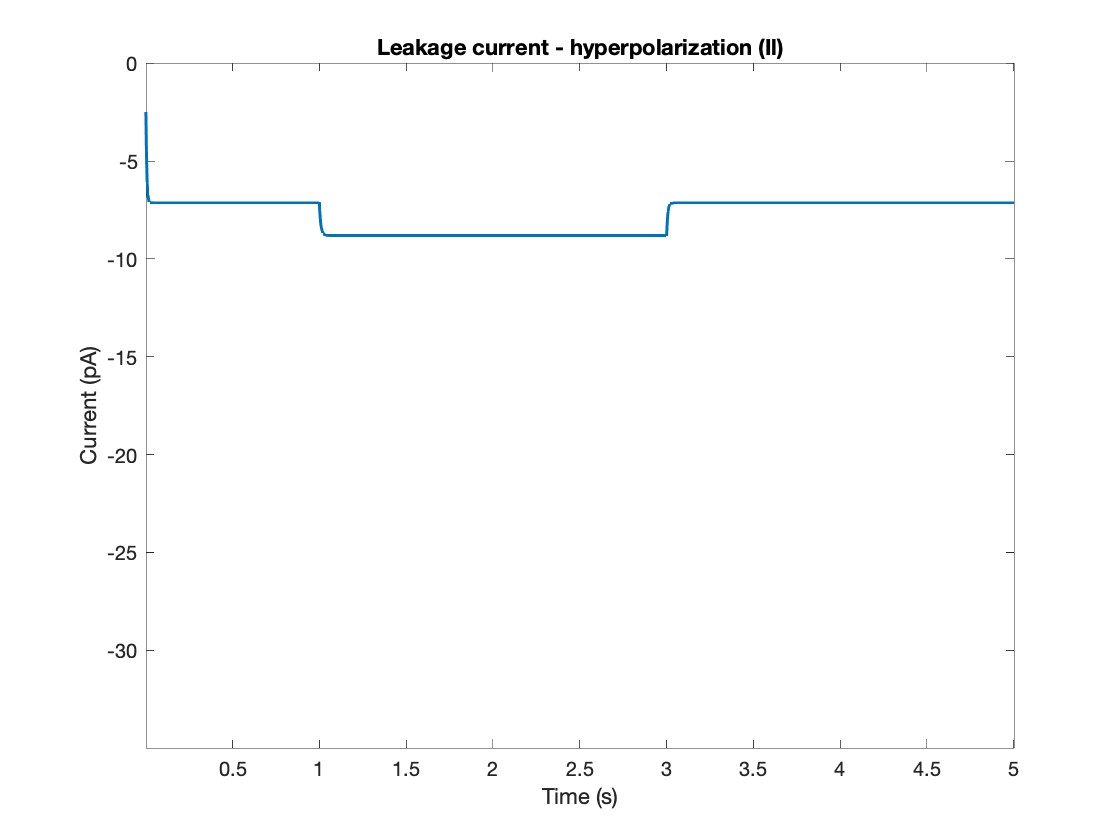

% Compute currents.
Il_30 = calcIl(V_30);
Il_20 = calcIl(V_20);
Il_10 = calcIl(V_10);

% Plot the results.
plot(t_10, Il_10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-35 0])
title('Leakage current - hyperpolarization (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')

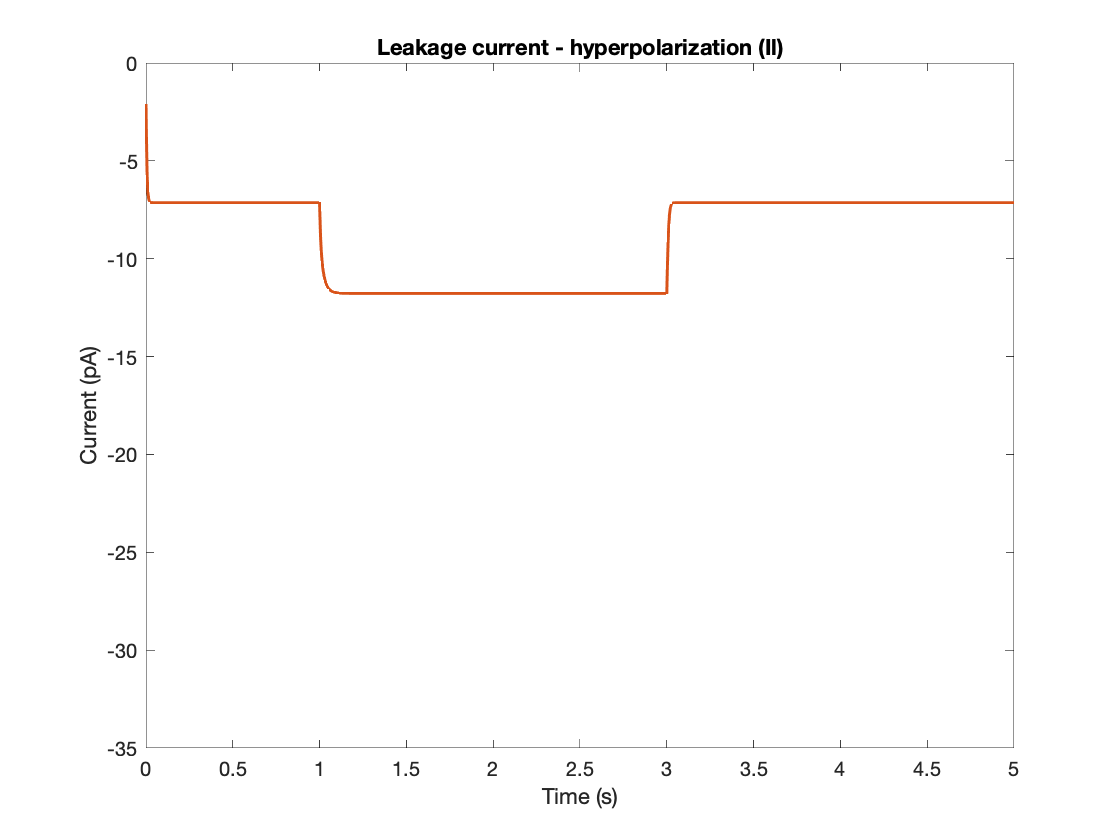

figure()

plot(t_20, Il_20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-35 0])
title('Leakage current - hyperpolarization (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')

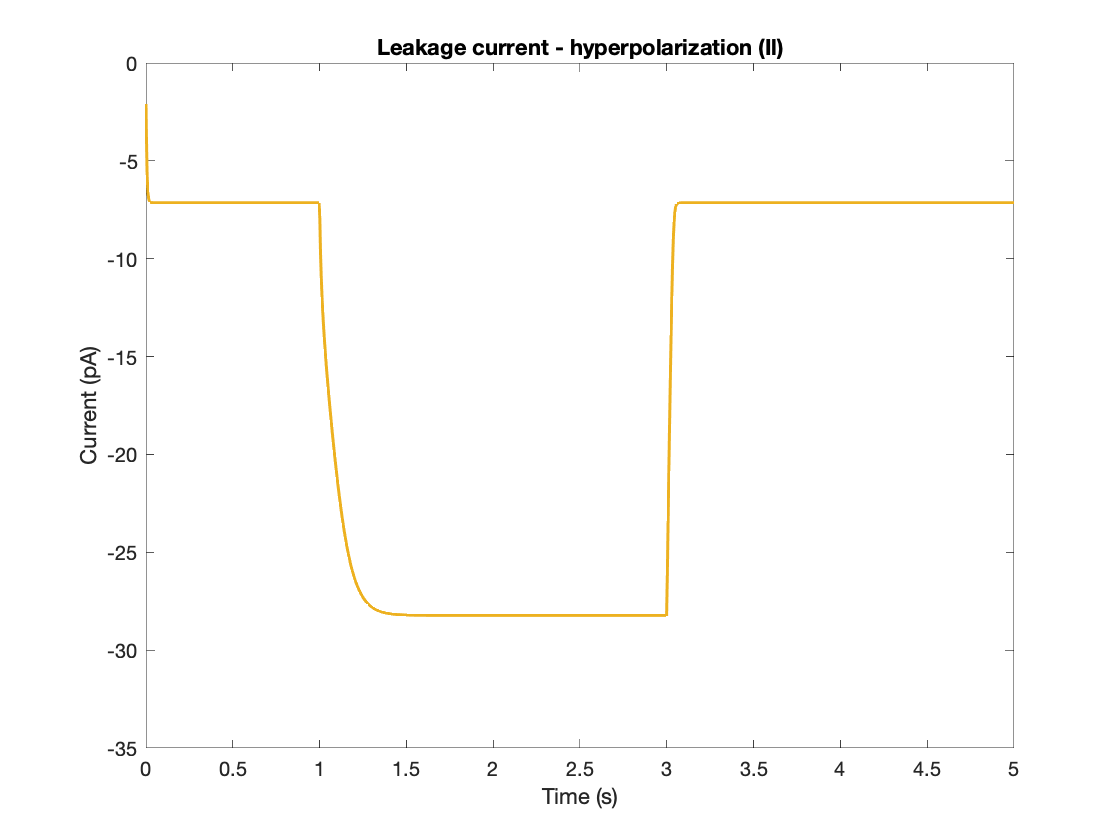

figure()

plot(t_30, Il_30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-35 0])
title('Leakage current - hyperpolarization (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()
% legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Leakage current (depolarization)*

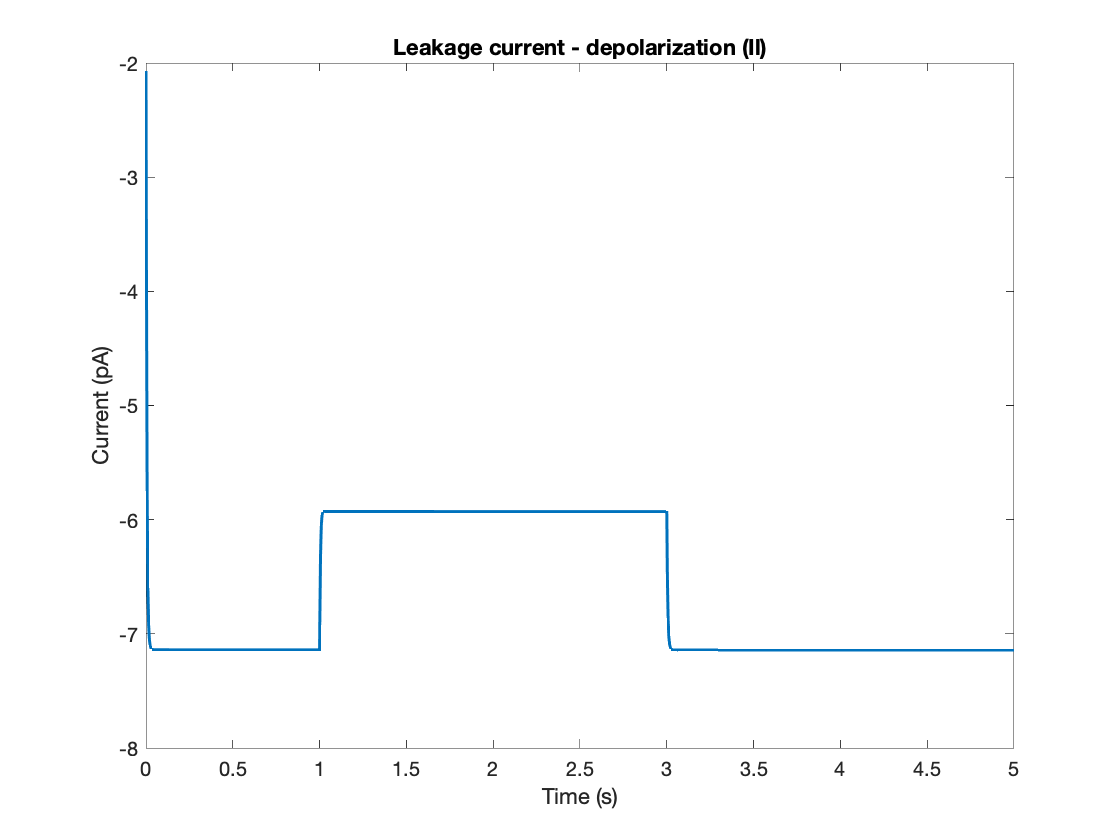

% Compute currents.
Il30 = calcIl(V30);
Il20 = calcIl(V20);
Il10 = calcIl(V10);

% Plot the results.
plot(t10, Il10, 'LineWidth', 1.5, 'Color', '#0072BD')
ylim([-8 -2])
title('Leakage current - depolarization (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')

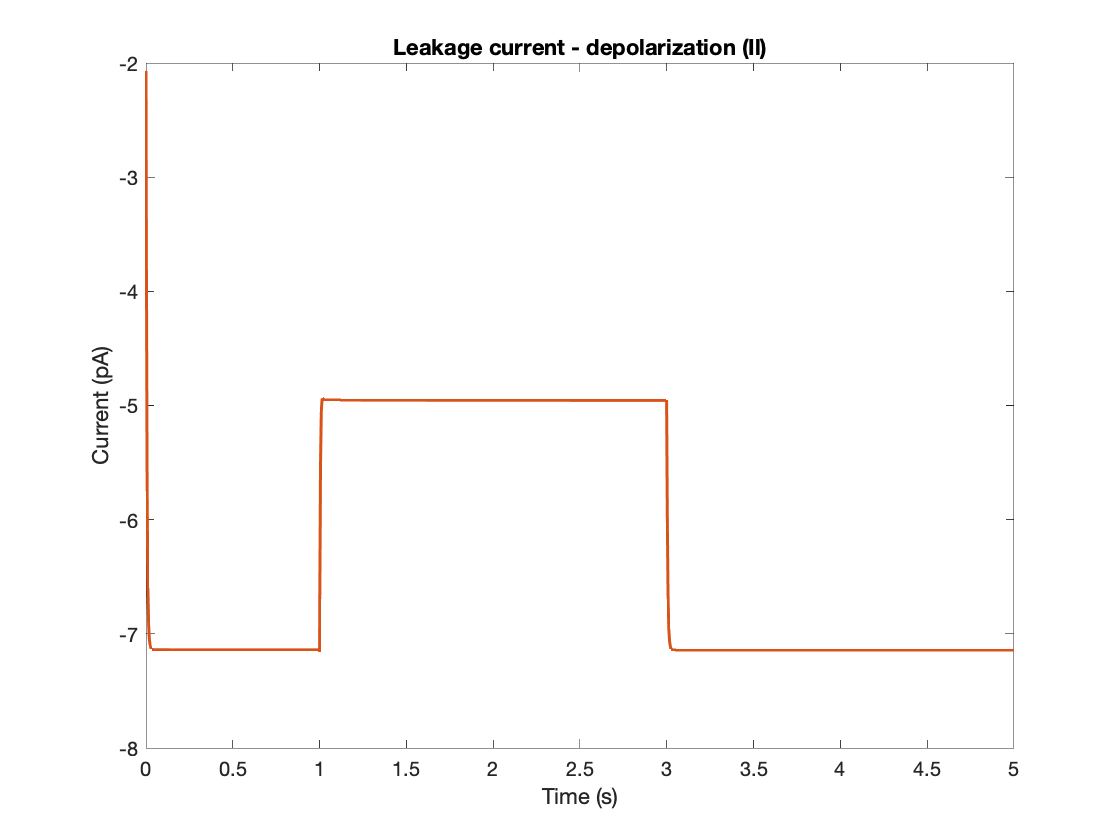

figure()

plot(t20, Il20, 'LineWidth', 1.5, 'Color', '#D95319')
ylim([-8 -2])
title('Leakage current - depolarization (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')

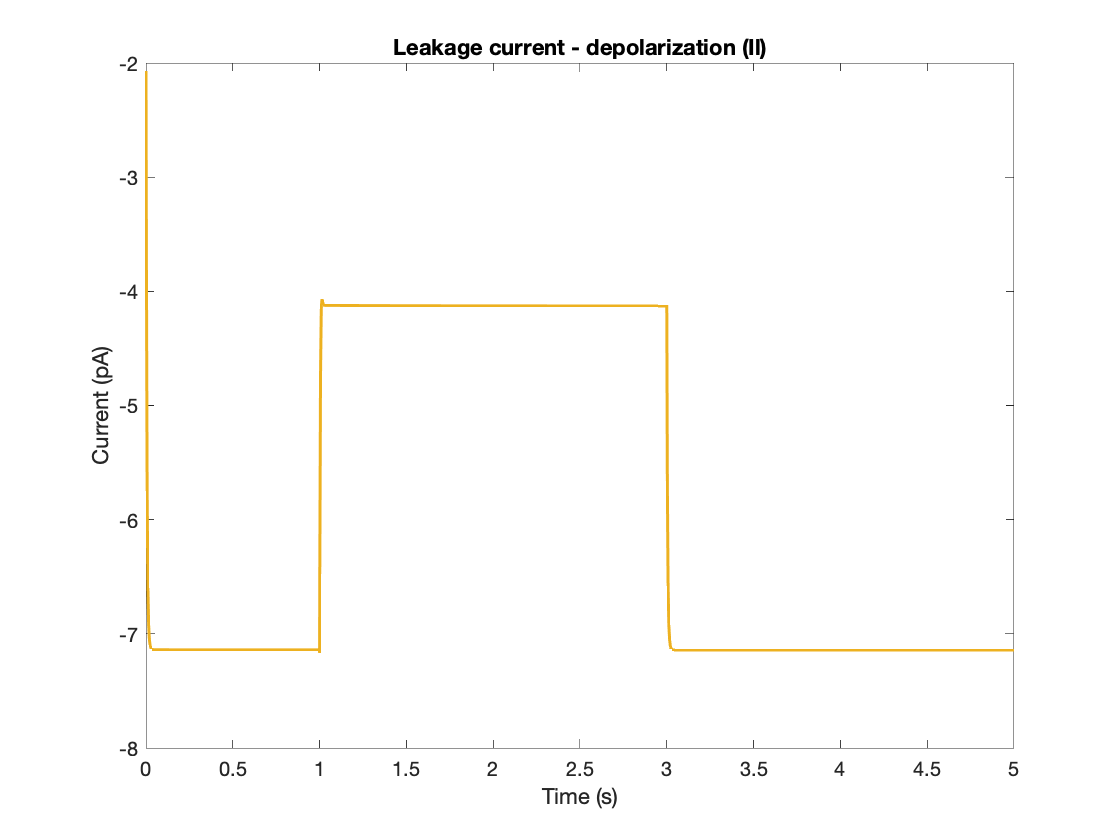

figure()

plot(t30, Il30, 'LineWidth', 1.5, 'Color', '#EDB120')
ylim([-8 -2])
title('Leakage current - depolarization (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')

figure()
% legend('30 pA injection','20 pA injection','10 pA injection')